# 度数分布，箱ひげ図，累積分布関数で標本の性質を確認する

ワークスペース変数を消去，コマンドウィンドウを初期化，すべてのFigureウィンドウを閉じる．

clear;clc;close all;
rng(1);

異なる平均と標準偏差を持つ分布を作る

N=100;
x=normrnd(1,1,[2*N,1]);
y=normrnd(-1,0.5,[N,1]);

度数分布(ヒストグラム)を描く

figure
tiledlayout('horizontal');
set(gcf,'position',[320, 1298, 560*2 420]);
nexttile

階級の基本設定を使う

histogram(x);hold on;grid on;set(gca,'fontname','メイリオ','fontsize',12);
histogram(y);
xlabel('$x$','Interpreter','latex');
ylabel('頻度');
title('階級幅：基本設定');

階級を自分で設定する

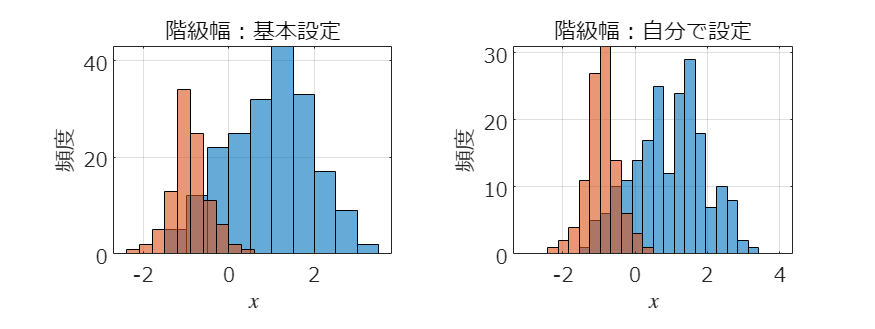

nexttile
edges=linspace(-3,4,25);
histogram(x,edges);hold on;grid on;set(gca,'fontname','メイリオ','fontsize',12);
histogram(y,edges);
xlabel('$x$','Interpreter','latex');
ylabel('頻度');
title('階級幅：自分で設定');
exportgraphics(gcf,'fig_histSample.pdf');

箱ひげ図と(経験的)累積分布関数を描く

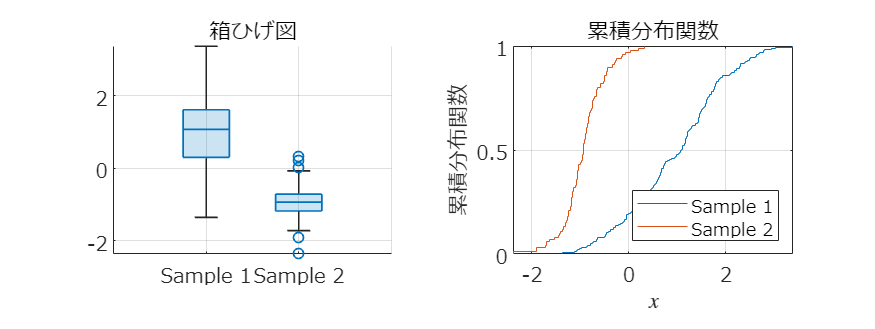

figure
tiledlayout('horizontal');
set(gcf,'position',[320, 1298, 560*2 420]);
nexttile
groupNum=categorical([ones(size(x));2*ones(size(y))], ...
    [1 2],{'Sample 1' 'Sample 2'});
boxchart(groupNum,[x;y]);
grid on;
set(gca,'fontname','メイリオ','fontsize',12);
title('箱ひげ図');

nexttile
ecdf(x);hold on;grid on;
set(gca,'fontname','メイリオ','fontsize',12);
ecdf(y);xlabel('$x$','Interpreter','latex');ylabel('累積分布関数');
legend({'Sample 1','Sample 2'},'Location','southeast');
title('累積分布関数')
exportgraphics(gcf,'fig_boxchartSample.pdf');

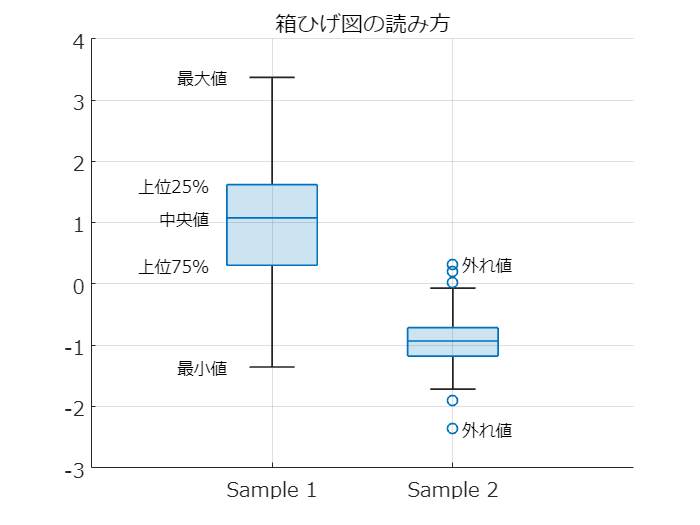

figure
groupNum=categorical([ones(size(x));2*ones(size(y))], ...
    [1 2],{'Sample 1' 'Sample 2'});
boxchart(groupNum,[x;y]);
grid on;
set(gca,'fontname','メイリオ','fontsize',12);
title('箱ひげ図の読み方');
text(0.75,max(x),'最大値','HorizontalAlignment','right','FontSize',10,'FontName','メイリオ');
text(0.65,prctile(x,75),'上位25%','HorizontalAlignment','right','FontSize',10,'FontName','メイリオ');
text(0.65,prctile(x,50),'中央値','HorizontalAlignment','right','FontSize',10,'FontName','メイリオ');
text(0.65,prctile(x,25),'上位75%','HorizontalAlignment','right','FontSize',10,'FontName','メイリオ');
text(0.75,min(x),'最小値','HorizontalAlignment','right','FontSize',10,'FontName','メイリオ');
text(2.05,min(y),'外れ値','HorizontalAlignment','left','FontSize',10,'FontName','メイリオ');
text(2.05,max(y),'外れ値','HorizontalAlignment','left','FontSize',10,'FontName','メイリオ');
exportgraphics(gcf,'fig_boxchartExplanation.pdf');